Příklady k Procvičení:

clear all;
close all;

# Spojitá rozdělení pravděpodobnosti

## 1. Rovnoměrné rozdělení

příklad 6: Funkce náhodné číslo generuje data z rovnoměrného rozdělení s parametry a=0, b=1. Transformujte tato data tak, aby a=10 a b=15. Tj. byla rovnoměrně rozdělena mezi <10,15>.

x=unifrnd(0,1);
y=5*x+10

y = 12.4872

Příklad 7: Ověřte výpočtem správnost střední hodnoty, rozptylu a směrodatné odchylky rovnoměrného rozdělení. Zjistěte dále šikmost a špičatost. 

syms a b x 
fx=1/(b-a)

$$fx = -\frac{1}{a-b}$$

EX=int(x*fx,a,b);
EX=simplify(EX)

$$EX = \frac{a}{2}+\frac{b}{2}$$


DX=int((x-EX)^2*fx,a,b);
DX=simplify(DX)

$$DX = \frac{{\left(a-b\right)}^{2}}{12}$$


sigma=sqrt(DX)

$$sigma = \sqrt{\frac{{\left(a-b\right)}^{2}}{12}}$$


sikmost=int((x-EX)^3*fx,a,b)/sigma^3

$$sikmost = 0$$


spicatost=int((x-EX)^4*fx,a,b)/sigma^4-3

$$spicatost = -\frac{6}{5}$$

Příklad 8: Náhodná veličina X má rovnoměrné rozdělení. Jaké jsou parametry a a b, jestliže jste zjistily z dat, že střední hodnota výběru je 1 a rozptyl je 3.

syms a b
[a,b]=solve((a+b)/2 == 1, (b-a)^2/12 == 3)

$$a = \left(\begin{array}{c} 4\\ -2 \end{array}\right)$$

$$b = \left(\begin{array}{c} -2\\ 4 \end{array}\right)$$

## 2. Exponenciální rozdělení

Příklad 12: Doba do poruchy zařízení lze popsat exponenciálním rozdělením. Data o poruchách máte uvedeny v souboru P0512.mat. Vypočtěte parametry exponenciálního rozdělení a střední dobu do poruchy (střední hodnota rozdělení). 

data = importdata('P0512.mat');
lambda = 1/expfit(data)

lambda = 0.0020

EX = expfit(data) %hodin

EX = 497.6095

Příklad 13: Doba do poruchy zařízení je popsána exponenciálním rozdělením, kde střední doba do poruchy E(T)=2000 h. Vygenerujte 10, 100 a 1000 dat z tohoto rozdělení a vypočtěte z dat střední hodnotu a rozptyl. Všimněte si, že pravděpodobně 1000 vstupních dat bude mít nejblíže k střední hodnotě 2000 h.

Pro vektor 1000 dat vypočtěte medián. Všimněte si, že medián není roven střední hodnotě. 

a=exprnd(2000,1,10);
mean(a)

ans = 1.6521e+03


b=exprnd(2000,1,100);
mean(b)

ans = 1.9749e+03


c=exprnd(2000,1,1000);
mean(c)

ans = 1.9680e+03

median(c)

ans = 1.2955e+03

Příklad 14: Vypočtěte z hustoty pravděpodobnosti střední hodnotu, rozptyl, směrodatnou odchylku, šikmost a špičatost.

syms lambda x positive
fx=lambda*exp(-lambda*x);

EX=int(x*fx,0,inf);
EX=simplify(EX)

$$EX = \frac{1}{\lambda }$$


DX=int((x-EX)^2*fx,0,inf);
DX=simplify(DX)

$$DX = \frac{1}{\lambda^{2}}$$


sigma=sqrt(DX)

$$sigma = \frac{1}{\lambda }$$


sikmost=int((x-EX)^3*fx,0,inf)/sigma^3

$$sikmost = 2$$


spicatost=int((x-EX)^4*fx,0,inf)/sigma^4-3

$$spicatost = 6$$

Příklad 15: Doba opravy má exponenciální rozdělení. Určete střední dobu opravy, jestliže do 60 minut je opraveno 30 % výrobků.

%neznáme lambda
mi = -60/log(1-0.3) %střední doba do opravy je 168 hodin

mi = 168.2204

lambda = 1/mi

lambda = 0.0059

Příklad 16: Doba do poruchy zařízení má exponenciální rozdělení s parametrem λ. Jaká je pravděpodobnost, že mezi dvěma po sobě jdoucími poruchami uběhne alespoň 3/λ hodin. 

syms lambda positive
t = 3/lambda

$$t = \frac{3}{\lambda }$$

Fx = 1-exp(-t*lambda)

$$Fx = 1-{\mathrm{e}}^{-3}$$

Rx = exp(-lambda*t)

$$Rx = {\mathrm{e}}^{-3}$$

Příklad 17: Výrobek má střední dobu do poruchy 3 roky. Jaká je pravděpodobnost, že se porouchá v záruce, tj. v prvních dvou letech provozu. 

lambda = 1/3;
Fx = 1 - exp(-lambda*2)

Fx = 0.4866

Příklad 17a:V souboru P0517a.xlsx máte data o poruchách komponenty. Data jsou v prvním sloupci. Určete:

- Parametry exponenciálního rozdělení

- Zjistěte pravděpodobnost, že se komponenta porouchá do 10000 hodin

- Zjistěte pravděpodobnost, že na výrobku budou dvě poruchy komponenty za jeden rok, tj. 8640 h.

x = importdata("P0517a.xlsx").List1(:,1);
%a)
lambda = expfit(x) %lambda

lambda = 5.9539e+03


%b)
Pb = 1- exp(-10000/lambda)

Pb = 0.8135


%b)
Pc = poisspdf(2,8640/lambda)

Pc = 0.2467

Příklad 17b: Testuje se životnost 100 výrobků. Doba zkoušky trvá 10000 hodin. Celkem bylo zaznamenáno 79 poruch, viz soubor P0517b.xlsx. Výrobky po poruše nejsou nahrazeny novými. V čase 10000 hodin je zkouška ukončena (21 výrobků). Určete parametry exponenciálního rozdělení. 

clear x
x=importdata("P0517b.xlsx").List1(:,1)';
cens(1:79) = 0;
cens(80) = 1;
freq(1:79) = 1;
freq(80) = 21;
x(80) = 10000;
EX = expfit(x,0.05,cens,freq)

EX = 6.3535e+03

## 3. Weibullovo rozdělení

Příklad 19: Nakreslete graf distribuční funkce, kde parametr a = 1 a parametr b bude po řadě 0.8; 1, 1.5, 2, 2.5, 3 a 10. Zdůvodněte výsledky. 

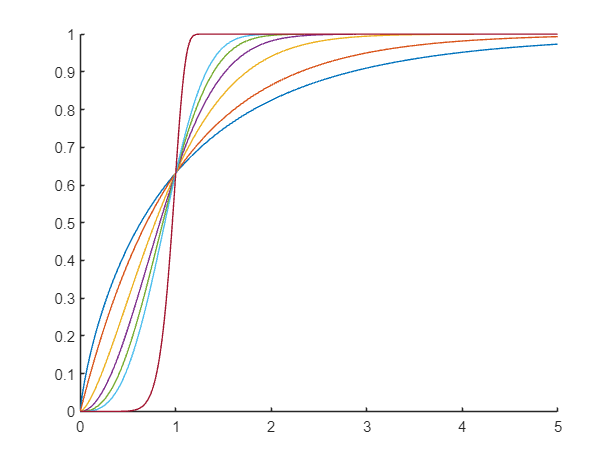

a = 1;
b = [0.8, 1, 1.5, 2, 2.5, 3, 10];
t = 0:0.01:5;
figure
hold on
for i=1:length(b)
    plot(t,1-exp(-(t./a).^b(i)))
end
hold off

Příklad 20: Poruchovost degradujícího zařízení je popsána Weibullovým rozdělením s parametry a = 3 roky a parametr b = 1.5. Určete střední dobu do poruchy (střední hodnota) zařízení. A určete pravděpodobnost, že se zařízení porouchá v době záruky, tj. do dvou let. 

a = 3; b = 1.5;
m=wblstat(a,b)

m = 2.7082

Pb = wblcdf(2,a,b)

Pb = 0.4198

Příklad 21: Zjistěte z dat o poruchovosti výrobku, které jsou uloženy v souboru P0521.mat, parametry Weibullova rozdělení. 

clear x
x = importdata("P0521.mat");
a=wblfit(x)

a =   269.4155    5.4606


Příklad 21a: Zjistěte z dat o poruchovosti výrobku, které jsou uloženy v souboru P0521a.mat, parametry Weibullova rozdělení. 

clear x
x=importdata("P0521a.mat");
a = wblfit(x)

a =   242.3323    1.0948


Příklad 21b: Příklad vychází z P0517b.Testuje se životnost 100 výrobků. Doba zkoušky trvá 10000 hodin. Celkem bylo zaznamenáno 79 poruch. Výrobky po poruše nejsou nahrazeny novými. V čase 10000 hodin je zkouška ukončena (21 výrobků). Určete parametry Weibullova rozdělení. Vstupní data viz soubor P0521b.xlsx

clear x
x = importdata("P0521b.xlsx").List1(:,1)';
cens(1:79) = 0;
cens(80) = 1;
freq(1:79) = 1;
freq(80) = 21;
x(80) = 10000;
format long
par = wblfit(x,0.05,cens,freq)

par = 1.0e+03 *

   6.336125709314095   0.000953046150783


format short

## 4. Normální rozdělení

Příklad 22: Nakreslete graf, kde budou vyneseny hustoty pravděpodobnosti z normálního rozdělení s následujícími parametry:

- 𝜇(X) = 0;  𝜎^2 = 1

- 𝜇(X) = 0;  𝜎^2 = 4

- 𝜇(X) = 4;  𝜎^2 = 1

- 𝜇(X) = 4;  𝜎^2 = 4

Rozsah vodorovné osy volte <-10, 10>. Uvědomte si, jakým způsobem se odlišují jednotlivé příklady od základního uvedeného v bodu a. 

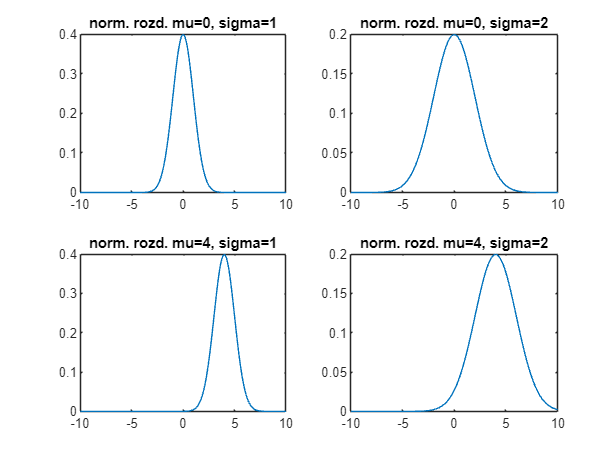

clear x y
x = -10:0.1:10;
figure
subplot(2,2,1)
y = normpdf(x,0,1);
plot(x,y)
title('norm. rozd. mu=0, sigma=1')
subplot(2,2,2)
y = normpdf(x,0,2);
plot(x,y)
title('norm. rozd. mu=0, sigma=2')
subplot(2,2,3)
y = normpdf(x,4,1);
plot(x,y)
title('norm. rozd. mu=4, sigma=1')
subplot(2,2,4)
y = normpdf(x,4,2);
plot(x,y)
title('norm. rozd. mu=4, sigma=2')

Příklad 24: Máte normální rozdělení s parametry                               . Vypočtěte následující hodnoty:

- 20% kvantil

- 50% kvantil

- Ze znalosti výsledku z bodu a) zpaměti 80% kvantil

-  F(x = 3.5)

-  F(x = 8)

- Zpaměti ze znalosti výsledku z bodu d) F(x = 6.5)

mu = 5; %střední hodnota takže max je 10
sigma = 2;
a = norminv(0.2,mu,sigma)

a = 3.3168

b = norminv(0.5,mu,sigma)

b = 5

%c = 10-a
c= norminv(0.8,mu,sigma)

c = 6.6832

d=normcdf(3.5,mu,sigma)

d = 0.2266

e = normcdf(8,mu,sigma)

e = 0.9332

%f = 1 - d
f = normcdf(6.5,mu,sigma)

f = 0.7734

Příklad 25: Délka výrobku v mm má N(𝜇 =50mm; 𝜎^2 = 0.49mm×mm). Určete pravděpodobnost, že rozměr výrobku bude mezi 49 a 51 mm. 

mu = 50; sigma = 0.7;
Pa = normcdf(51,mu,sigma) - normcdf(49,mu,sigma)

Pa = 0.8469

Příklad 26: Výsledky měření jsou zatíženy jen normálně rozdělenou náhodnou chybou se směrodatnou odchylkou 3 mm. 

- Jaká je pravděpodobnost, že při měření bude chyba v intervalu (-2 mm, 5 mm).

- Máte 3 výrobky, jaká je pravděpodobnost, že alespoň u jednoho výrobku bude chyba mimo tento interval. 

%N(0,3)
Pa = normcdf(5,0,3) - normcdf(-2,0,3)

Pa = 0.6997


Pb = 1 - binopdf(3,3,Pa)

Pb = 0.6574

Příklad 27: Výsledky radarového měření jsou zatíženy normálně rozdělenou náhodnou chybou s nulovou střední hodnotou, která s pravděpodobností 0.95 nepřesahuje +-20m. Určete směrodatnou odchylku měření.

%kvantil 2,5% a 97,5% normovaného normálního rozdělení
%Interval uprostřed mí 95 % a zjistíme sigmu
%použijeme inverzní transformaci z normovaného normálního na normální
%rozdělení

zmin=norminv(0.025,0,1);
zmax=norminv(0.975,0,1);
%zmin=-1.96    zmax=1.96

%z=(x-mu)/sigma, z toho z*sigma=x (mu je nula)
%+20 metrů odpovídá 1.96 sigma
%-20 metrů odpovídá -1.96 sigma

sigma=20/zmax

sigma = 10.2043

Příklad 30: X je náhodná veličina s rozdělením N(𝜇 = 10;𝜎^2 = 20) . Jak velké musí být číslo x, aby náhodná veličina nabyla hodnoty z intervalu (3, x) s pravděpodobností 25 %.

mu = 10;
sigma = sqrt(20);
%p = 0.25 + normcdf(3,mu,sigma);
p = 0.25;
x = norminv(p,mu,sigma)

x = 6.9836

Příklad 31: Pravděpodobnost, že náhodná veličina nabude vyšší hodnoty než 59.6 je 0.2119. Pravděpodobnost, že nabude hodnoty menší než 57.2 je 0.7258. Náhodná veličina je z normálního rozdělení. Vypočtěte hodnoty parametrů. 

%N(0,1)
Pa = 1 - 0.2119;
Pb = 0.7258;

za = norminv(Pa,0,1);
zb = norminv(Pb,0,1);
syms mu 
syms sigma positive
[mu,sigma] = solve((59.6-mu)/sigma==za, (57.2-mu)/sigma==zb)

$$mu = \frac{224767742652226772}{4496543271857545}$$

$$sigma = \frac{54043195528445952}{4496543271857545}$$

Příklad 32: Nalezněte 1, 5, 10, 50, 90, 95 a 99% kvantil normálního rozdělení s parametry N(𝜇=10; 𝜎^2=80) . Určete pravděpodobnost, že náhodná veličina bude záporná.

mu = 10;
sigma = sqrt(80);
q = [0.01, 0.05, 0.1, 0.5, 0.9, 0.95, 0.99];
for i=1:length(q)
    P(i) = norminv(q(i),mu,sigma);
end
P(end+1) = normcdf(0,mu, sigma);
P

P =   -10.8075   -4.7120   -1.4625   10.0000   21.4625   24.7120   30.8075    0.1318


Příklad 33: Máte naměřená data v souboru P0533.mat. Odstraňte data, která jsou odlehlá a následně zjistěte parametry normálního rozdělení. 

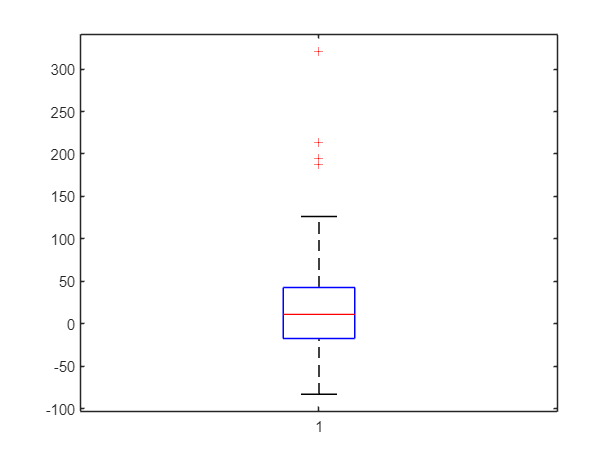

clear x
x = importdata('P0533.mat');
figure
boxplot(x)

x=sort(x)

x =   -83.1947  -75.5342  -72.0727  -70.1054  -68.4360  -60.0085  -53.0823  -47.9639  -44.4678  -43.3471  -43.2802  -40.2847  -38.3138  -36.2561  -34.8051  -34.7055  -32.8862  -32.3272  -29.1683  -25.5213  -24.6187  -23.9484  -23.9170  -23.5835  -23.2547  -22.9435  -21.9265  -18.5812  -14.0131  -13.5612  -11.7812  -11.3423   -9.0461   -8.7446   -4.1540   -3.3955   -2.1243   -1.9626   -1.7501   -1.4260   -1.1149   -0.8988   -0.4798    1.0092    1.2957    1.6115    2.0921    2.1912    2.2351    2.9386


x=x(1:end-4)

x =   -83.1947  -75.5342  -72.0727  -70.1054  -68.4360  -60.0085  -53.0823  -47.9639  -44.4678  -43.3471  -43.2802  -40.2847  -38.3138  -36.2561  -34.8051  -34.7055  -32.8862  -32.3272  -29.1683  -25.5213  -24.6187  -23.9484  -23.9170  -23.5835  -23.2547  -22.9435  -21.9265  -18.5812  -14.0131  -13.5612  -11.7812  -11.3423   -9.0461   -8.7446   -4.1540   -3.3955   -2.1243   -1.9626   -1.7501   -1.4260   -1.1149   -0.8988   -0.4798    1.0092    1.2957    1.6115    2.0921    2.1912    2.2351    2.9386


[mu,sigma]=normfit(x)

mu = 10.3857

sigma = 41.8544

Příklad 34: Jaká je pravděpodobnost, že po 200 hodinách provozu budou fungovat alespoň 3 výrobky z 5, jestliže doba do poruchy v hodinách je popsána $N\left(\mu =180\ hodin;\ \sigma^2 =400\ {hodin}^2 \right)$

mu = 180; sigma = sqrt(400);
p1 = 1 - normcdf(200,mu,sigma)

p1 = 0.1587


P = 1 - binocdf(2.5,5,p1)

P = 0.0310

## 5. Logaritmicko-normální rozdělení

Příklad 36: Nechť X je náhodná veličina s logaritmicko-normálním rozdělením s parametry  $\mu =3;\ \sigma^2 =$16. Vypočtěte pravděpodobnost, že data jsou v intervalu <2,4>. Vykreslete hustotu pravděpodobnosti. Zvolte maximum 5 a krok 0.001. Všimněte si nesymetričnosti dat. 

mu = 3; sigma = sqrt(16);
x = 0:0.001:5;
p = logncdf(4,mu,sigma) - logncdf(2,mu,sigma)

p = 0.0613

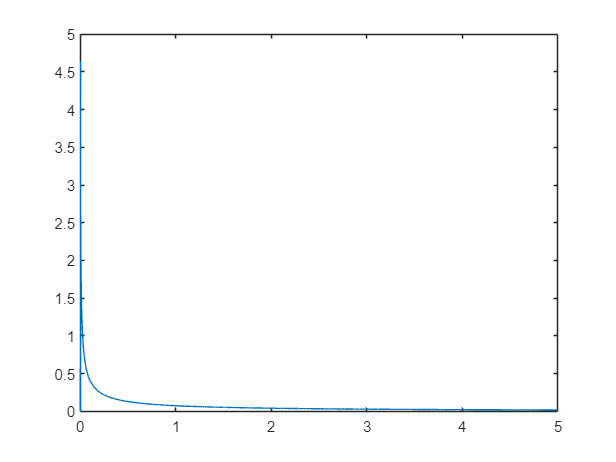

y = lognpdf(x,mu,sigma);
figure
plot(x,y)

## 6. Přesnost statistických charakteristik kvantitativních proměnných

Příklad 37: Vygenerujte 100 dat z logaritmicko-normálního rozdělení s parametry $\mu =4;\ \sigma^2 =5$. Vytvořte z nich krabicový graf, dale pomocí Weibullova a normálního papíru ověřte, zda byste mohli použít dané rozdělení. 

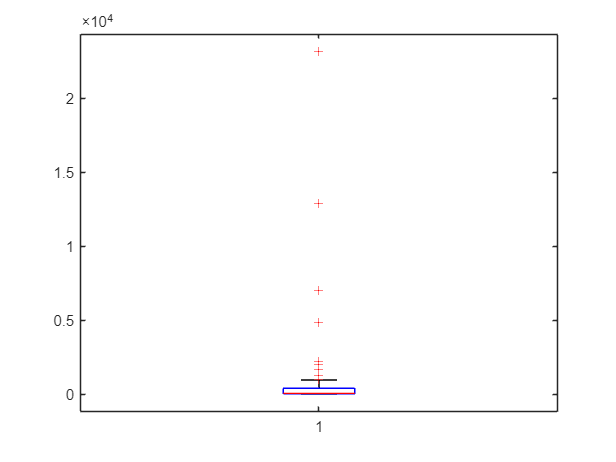

mu = 4; sigma = sqrt(5);
clear x
x = lognrnd(mu,sigma,1,100);
figure
boxplot(x)

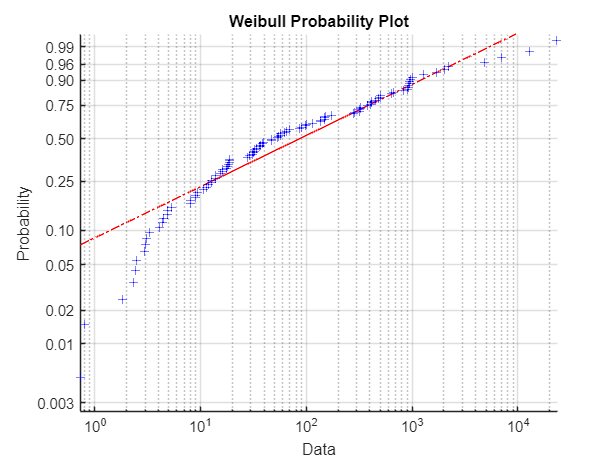

figure
wblplot(x)

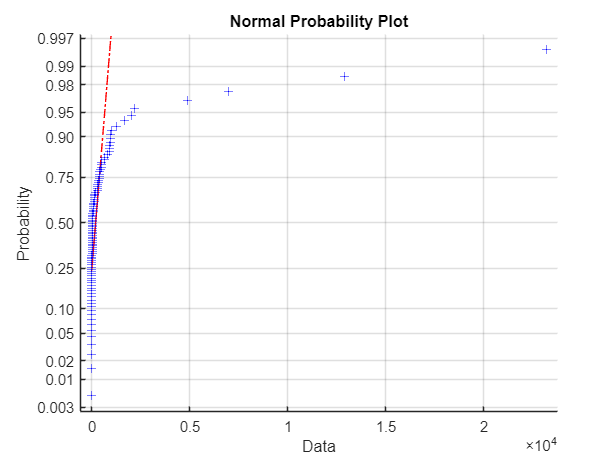

figure
normplot(x)

Příklad 38: Pro data uložená v souboru P0538.mat vytvořte krabicový graf. Co představují jednotlivé čáry v grafu. 

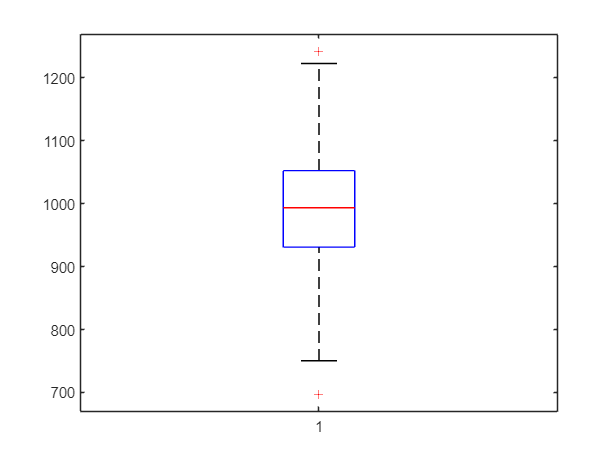

clear x
x = importdata("P0538.mat");
figure 
boxplot(x)

Příklad 29: Vygenerujte 1000 dat z následujících rozdělení a vytvořte z každého z nich krabicový graf. Následně ověřte pro data z bodu d), že data pochází z Weibullova nebo normálního rozdělení podle příslušného papíru.

- Exponenciální rozdělení se střední hodnotou 100 hodin

- Weibullovo rozdělení s parametrem a = 100, b = 1.5  

- Weibullovo rozdělení s parametrem a = 100, b = 3.5  

- Normální rozdělení s parametry $N\left(\mu =100;\ \sigma^2 =900\right)$

- Vyneste vygenerovaná data z bodů a až d do jednoho grafu (sloupce 1 až 4)

Výsledky porovnejte z pohledu rozptylu a šikmosti.

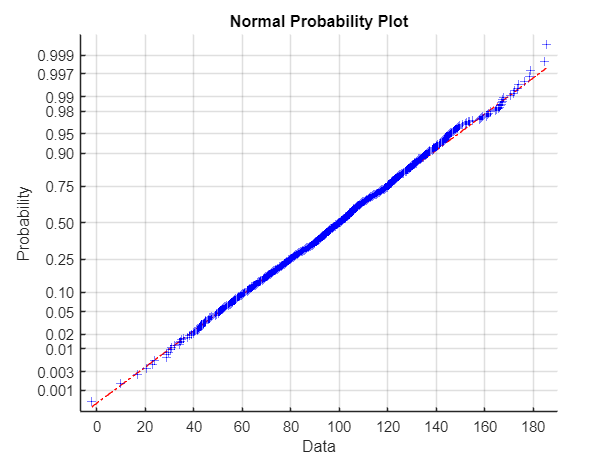

clear a b c d
a = exprnd(100,1,1000);
b = wblrnd(100,1.5,1,1000);
c = wblrnd(100,3.5,1,1000);
d = normrnd(100,sqrt(900),1,1000);
figure
normplot(d)

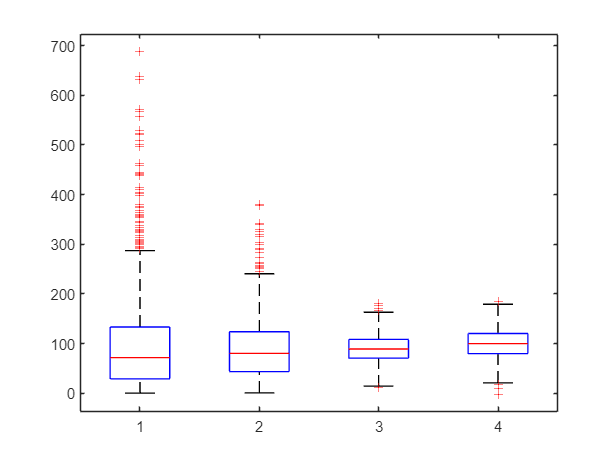

figure
boxplot([a,b,c,d], [ones(1,1000),2*ones(1,1000),3*ones(1,1000),4*ones(1,1000)])

Příklad 39: Bylo testováno, zda se rozměry výrobků mění v závislosti na intervalu mezi seřízením stroje. Intervaly mezi seřízením stroje byl 1, 2, 3 a 4 dny. Zkuste analyzovat data pomocí krabicového grafu a odhadněte z charakteru výsledků, zda dochází k posuvu přesnosti rozměrů (změna středních hodnot) a k rozptylu přesnosti dat. Data jsou uložena v souboru P0539.mat.

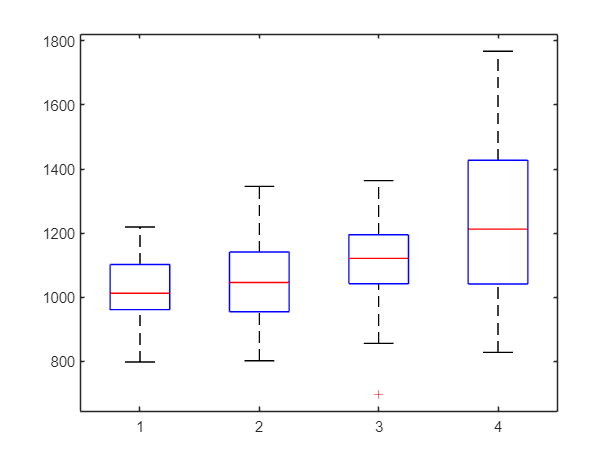

clear x
x=importdata("P0539.mat");
figure
boxplot(x)